clc
clear all
clf
addpath("FBA_Lecture/")

Introduction using linear programming to compute intracellurar Processes

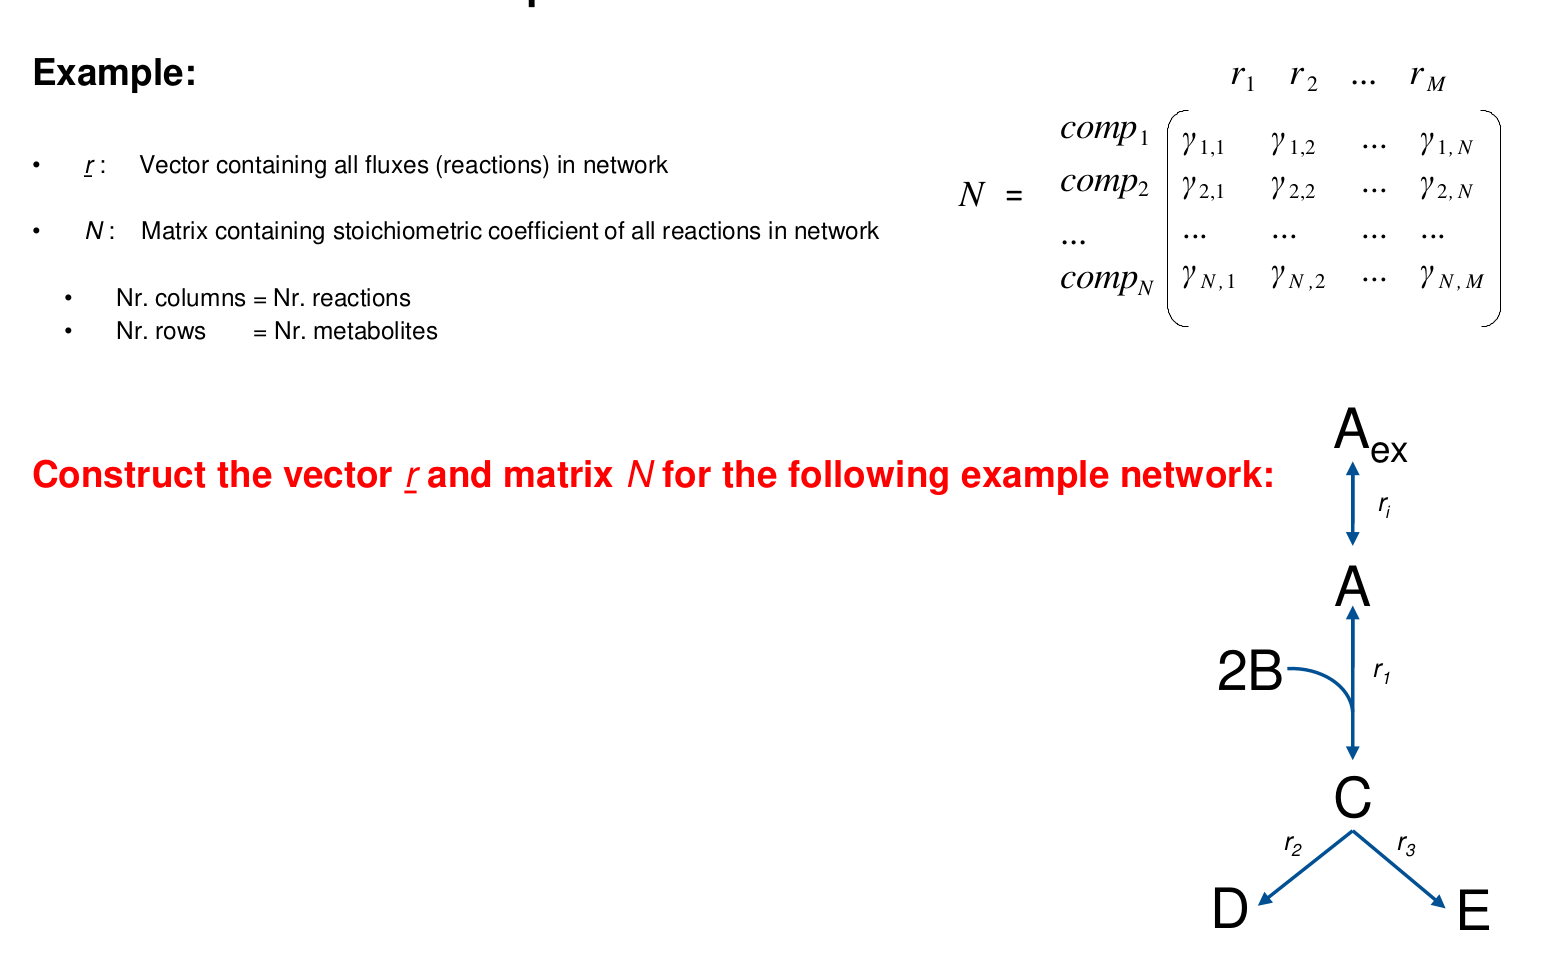

 
%reaction  ri  r1   r2  r3
NAex    = [-1   0   0   0] ; 
NA      = [ 1  -1   0   0] ;
NB      = [ 0  -2   0   0] ;
NC      = [ 0   1  -1  -1] ;
ND      = [ 0   0   1   0] ;
NE      = [ 0   0   0   1] ;
N       = [NAex;NA;NB;NC;ND;NE]  ;

%r_solution  = [ri  r1  r2  r3] ;

 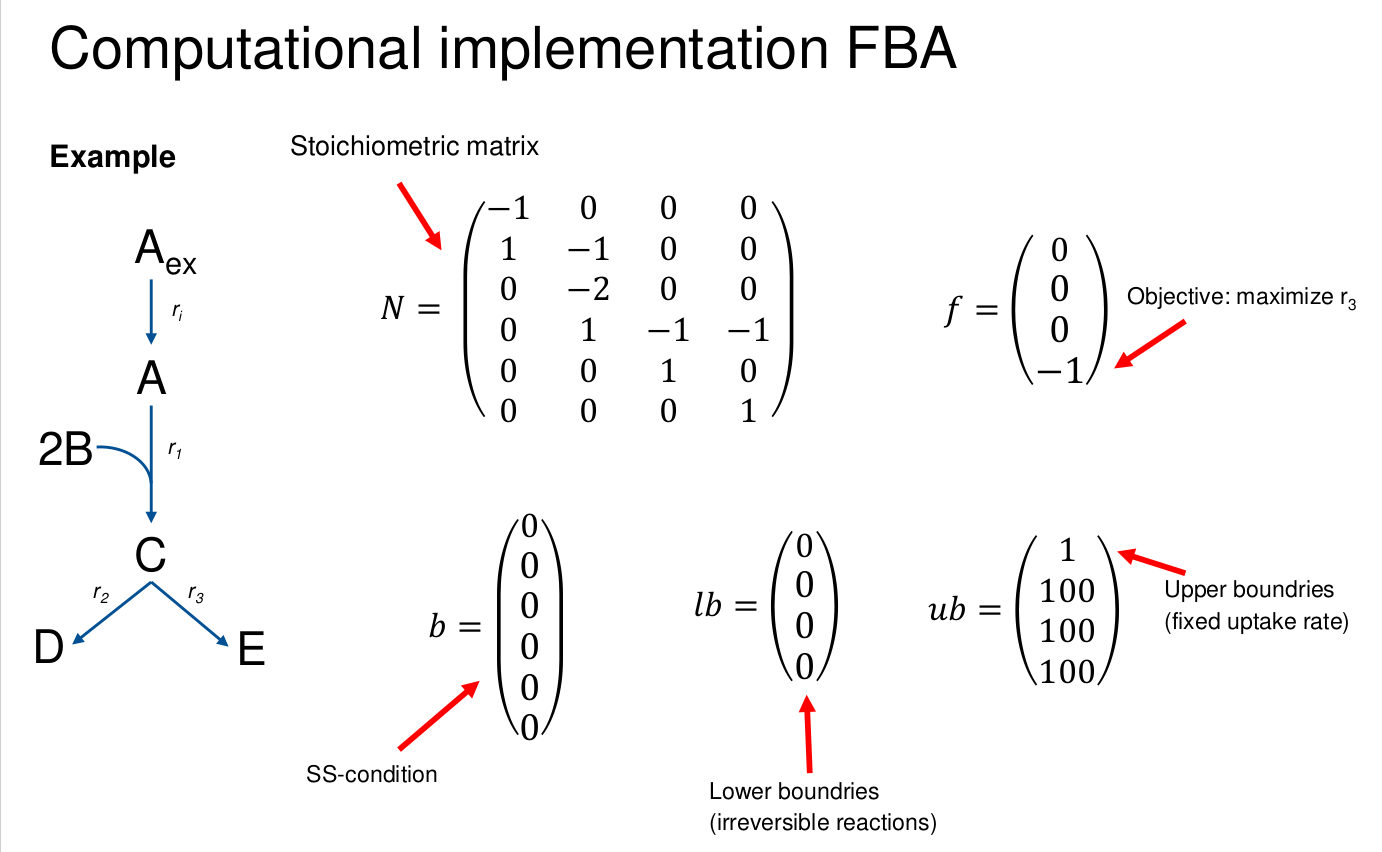

b  = zeros(size(N,1),1)             ; %Steady State Condition
lb = zeros(size(N,2),1)             ; %lower boundarys
ub = [1  100 100 100 ].'            ; %uper boundarys
f  = [0 0 0  -1].'                  ; %maximize r3
[x,fval,exitflag,output] = linprog (f, [ ], [ ],N, zeros(height(N),1), lb, ub);

Optimal solution found.



null(N)


ans =

  4×0 empty double matrix

